# **Wireless Communications**

# **CA#2 **

## Sogol Goodarzi

## 810198467

## Section 1. Narrowband Channel

## Question 1. 

### Part a.

clc;
clear all;
n = 1000;
N = 5000;
SNR = linspace(-20,20,n);
a = 1;
N0 = a^2./(10.^(SNR./10));
W = repmat(N0, [N, 1]);

#### 
$$w\left\lbrack m\right\rbrack =w_{\textrm{Re}} \left\lbrack m\right\rbrack +w_{\textrm{Im}} \left\lbrack m\right\rbrack \;\;\;\sim N\left(0,N_0 \right)$$


w_Re = sqrt(W/2).*randn(N, n);
w_Im = sqrt(W/2).*randn(N, n);

#### 
$$h\left\lbrack m\right\rbrack =h_{\textrm{Re}} \left\lbrack m\right\rbrack +h_{\textrm{Im}} \left\lbrack m\right\rbrack \;\;\;\;\sim N\left(0,1\right)$$


h_Re = sqrt(1/2)*randn(N, n);
h_Im = sqrt(1/2)*randn(N, n);

#### 
$$y\left\lbrack m\right\rbrack =y_{\textrm{Re}} \left\lbrack m\right\rbrack +y\left\lbrack m\right\rbrack$$


a = [-1,1];
x = [];
parfor i = 1:N
    x = [x ; randsample(a,n,true)];
end
y_Re = x.*h_Re + w_Re;
y_Im = x.*h_Im + w_Im;

#### 
$$p_e =p\left\lbrace y>0|x<0\right\rbrace +p\left\lbrace y<0|x>0\right\rbrace$$


delta = (y_Re+y_Im)/2;
pe_fading = sum(delta.*x < 0)/N;

#### Plotting $p_{e\;}$by considering fading:

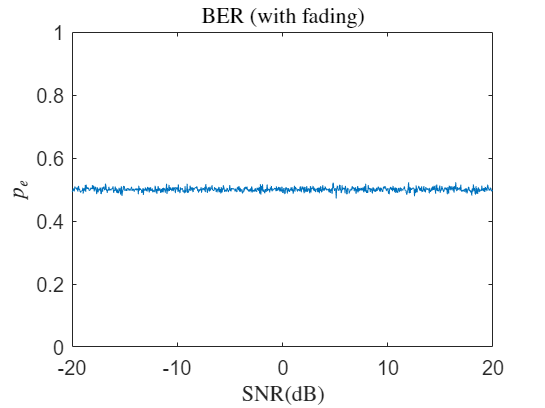

plot(SNR, pe_fading);
xlabel('SNR(dB)','Interpreter','latex');
ylabel('$p_{e}$','Interpreter','latex');
ylim([0 1]);
title('BER (with fading)','Interpreter','latex');

### Part b.

#### Plotting $p_{e\;}$without fading:

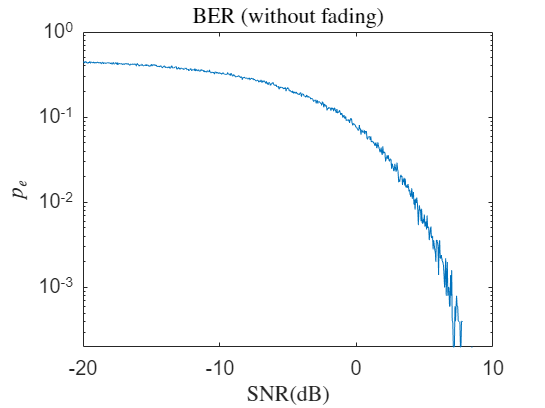

w_Re = sqrt(W/2).*randn(N, n);
w_Im = sqrt(W/2).*randn(N, n);
a = [-1,1];
x = [];
parfor i = 1:N
    x = [x ; randsample(a,n,true)];
end
y_Re = x + w_Re;
y_Im = x + w_Im;
delta = (y_Re + 1j.*y_Im)/2;
pe_non_fading = sum(delta.*x < 0)/N;
semilogy(SNR, pe_non_fading);
xlabel('SNR(dB)','Interpreter','latex');
ylabel('$p_{e}$','Interpreter','latex');
ylim([0 1]);
title('BER (without fading)','Interpreter','latex');

### Part c.

#### Plotting calculated BER and theoretic BER for non-fading case:

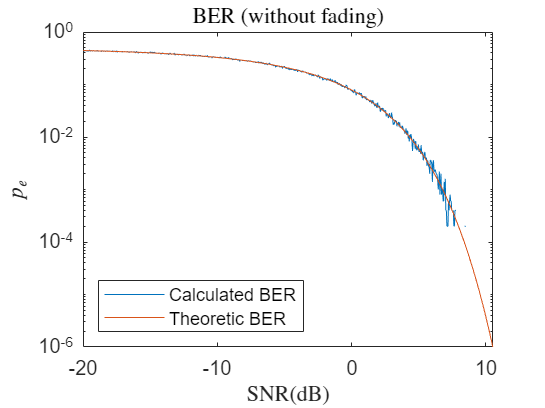

figure();
semilogy(SNR, pe_non_fading);
ylim([1e-6 1]);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('BER (without fading)',Interpreter='latex');
hold on
semilogy(SNR, qfunc(sqrt(2*(10.^(SNR./10)))));
legend(['Calculated BER'],['Theoretic BER'],'Location','southwest');
hold off

## Question 2. 

### Part a.

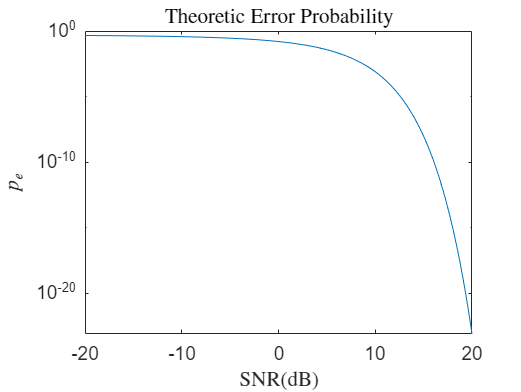

clc;
clear all;
n = 1000;
SNR = linspace(-20,20,n);
pe2_theoretic = qfunc(sqrt(10.^(SNR./10)));
semilogy(SNR, pe2_theoretic);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('Theoretic Error Probability',Interpreter='latex');

### Part b.

N = 5000;
a = 1;
N0 = a^2./(10.^(SNR./10));
W = repmat(N0, [N, 1]);
w1 = sqrt(W/2).*randn(N, n);
w2 = sqrt(W/2).*randn(N, n);
a = [-1,1];
x = [];
parfor i = 1:N
    x = [x ; randsample(a,n,true)];
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


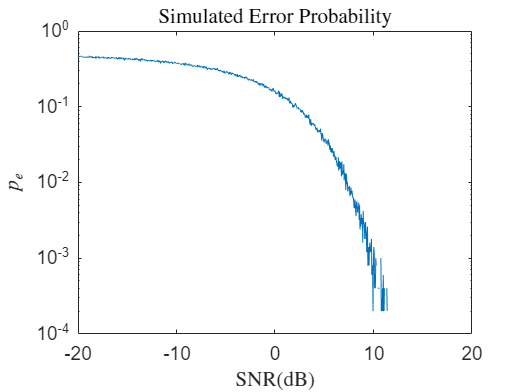

alpha = 1;
x1 = alpha*(x == -1);
x2 = alpha*(x == 1);
y1 = x1 + w1;
y2 = x2 + w2;
delta = y1 - y2;
pe2_simulation = sum(delta.*x > 0)/N;
semilogy(SNR, pe2_simulation);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('Simulated Error Probability',Interpreter='latex');

#### Plotting both graphs:

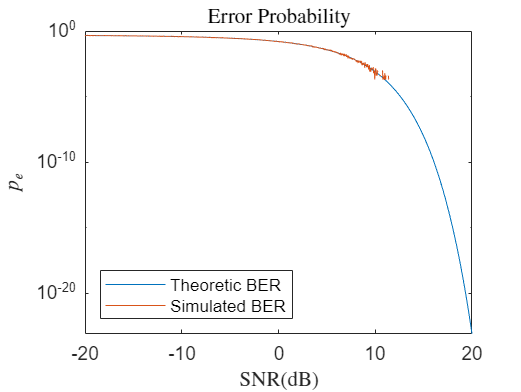

semilogy(SNR, pe2_theoretic);
hold on
semilogy(SNR, pe2_simulation);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('Error Probability',Interpreter='latex');
legend(['Theoretic BER'],['Simulated BER'],'Location','southwest');
hold off

## Question 3. 

### Part a.

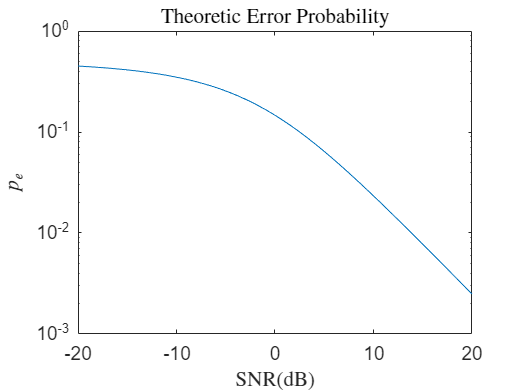

n = 1000;
SNR = linspace(-20,20,n);
a = 1;
N0 = a^2./(10.^(SNR./10));
pe3_theoretic = 1/2*(1-sqrt(10.^(SNR./10)./(1+10.^(SNR./10))));
semilogy(SNR, pe3_theoretic);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('Theoretic Error Probability',Interpreter='latex');

### Part b.

N = 5000;
W = repmat(N0, [N, 1]);
w_Re = sqrt(W/2).*randn(N, n);
w_Im = sqrt(W/2).*randn(N, n);
h_Re = sqrt(1/2)*randn(N, n);
h_Im = sqrt(1/2)*randn(N, n);

#### After removing channel effect:

#### 
$$y=x+w\times \frac{h^* }{|h|^2 }=x+\textrm{Noise}$$


#### 
$$w=w_{\textrm{Re}} +jw_{\textrm{Im}} \;\;\;\;,\;\;\;\;h=h_{\textrm{Re}} +jh_{\textrm{Im}}$$


#### 
$$w\times \frac{h^* }{|h|^2 }=\left(w_{\textrm{Re}} +jw_{\textrm{Im}} \right)\times \frac{h_{\textrm{Re}} -jh_{\textrm{Im}} }{{h_{\textrm{Re}} }^2 +{h_{\textrm{Im}} }^2 }=\frac{\left(w_{\textrm{Re}} h_{\textrm{Re}} +w_{\textrm{Im}} h_{\textrm{Im}} \right)}{{h_{\textrm{Re}} }^2 +{h_{\textrm{Im}} }^2 }+\frac{\left(h_{\textrm{Re}} w_{\textrm{Im}} -h_{\textrm{Im}} w_{\textrm{Re}} \right)}{{h_{\textrm{Re}} }^2 +{h_{\textrm{Im}} }^2 }j$$


#### 
$$\textrm{Noise}={\textrm{Noise}}_{\textrm{Re}} +j{\textrm{Noise}}_{\textrm{Im}}$$


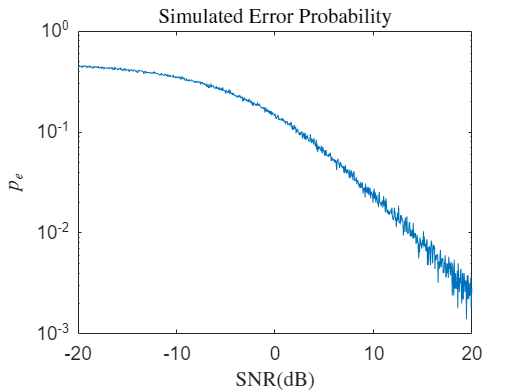

norm2_h = h_Re.^2 + h_Im.^2;
Noise_Re = (w_Re.*h_Re + w_Im.*h_Im)./norm2_h;
Noise_Im = (w_Im.*h_Re - w_Re.*h_Im)./norm2_h;
a = [-1,1];
x = [];
parfor i = 1:N
    x = [x ; randsample(a,n,true)];
end
y = x + Noise_Re + 1j.*Noise_Im;
pe3_simulation = sum(y.*x < 0)/N;
semilogy(SNR, pe3_simulation);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('Simulated Error Probability',Interpreter='latex');

#### Plotting both parts together (Q2 and Q3):

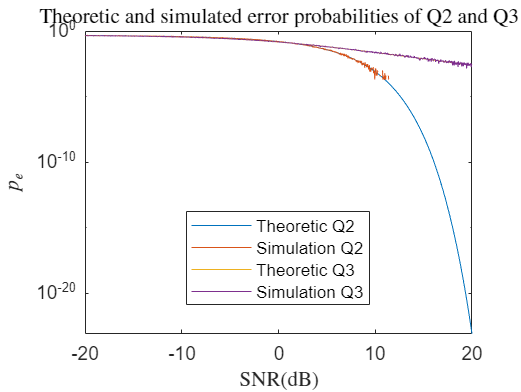

semilogy(SNR, pe2_theoretic, SNR, pe2_simulation, SNR, pe3_theoretic, SNR, pe3_simulation);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
legend(["Theoretic Q2", "Simulation Q2", "Theoretic Q3", "Simulation Q3"],'Location','best');
title('Theoretic and simulated error probabilities of Q2 and Q3',Interpreter='latex');

## Question 4. 

### Part a.

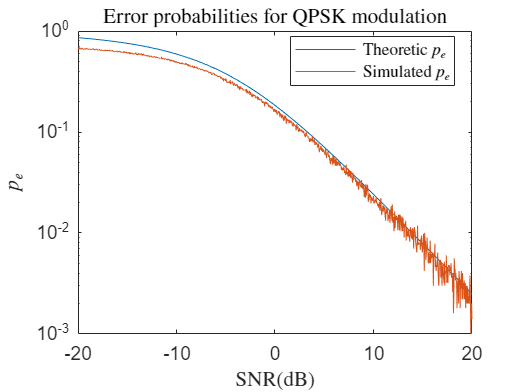

SNR = linspace(-20,20,n);
a = 1;
N0 = a^2./(10.^(SNR./10));
W = repmat(N0, [N, 1]);
pe4_theoretic = 1-sqrt(2*10.^(SNR./10)./(1+2*10.^(SNR./10)));
% Generating symbols:
a = [-1,1];
s1 = [];
s2 = [];
parfor i = 1:N
    s1 = [s1 ; randsample(a,n,true)];
    s2 = [s2 ; randsample(a,n,true)];
end
w_Re = sqrt(W/4).*randn(N, n, 2);
w_Im = sqrt(W/4).*randn(N, n, 2);
h_Re = sqrt(1/2)*randn(N, n);
h_Im = sqrt(1/2)*randn(N, n);
norm2_h = h_Re.^2 + h_Im.^2;
Noise1 = (w_Re(:,:,1).*h_Re + w_Im(:,:,1).*h_Im)./norm2_h;
Noise2 = (w_Re(:,:,2).*h_Re + w_Im(:,:,2).*h_Im)./norm2_h;
y1 = s1 + Noise1;
y2 = s2 + Noise2;
P_c = sum((s1.*y1 >0).*( s2.*y2 > 0))/N;
pe4_simulation = 1 - P_c;
semilogy(SNR, pe4_theoretic, SNR, pe4_simulation);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
legend(['Theoretic $p_{e}$'],['Simulated $p_{e}$'],'Location','best',Interpreter='latex');
title('Error probabilities for QPSK modulation',Interpreter='latex');

### Part b.

#### Plotting both parts together (Q2 and Q4):

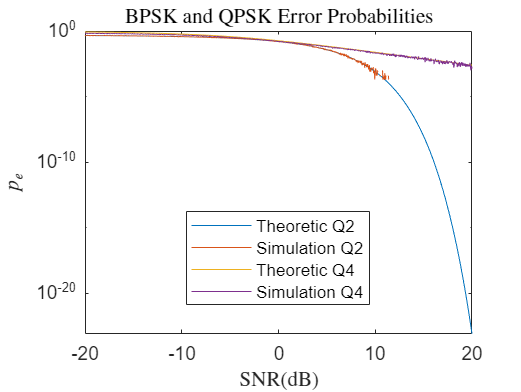

semilogy(SNR, pe2_theoretic, SNR, pe2_simulation, SNR, pe4_theoretic, SNR, pe4_simulation);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
legend(["Theoretic Q2", "Simulation Q2", "Theoretic Q4", "Simulation Q4"],'Location','best');
title('BPSK and QPSK Error Probabilities',Interpreter='latex');

## Question 5. 

### Part b.

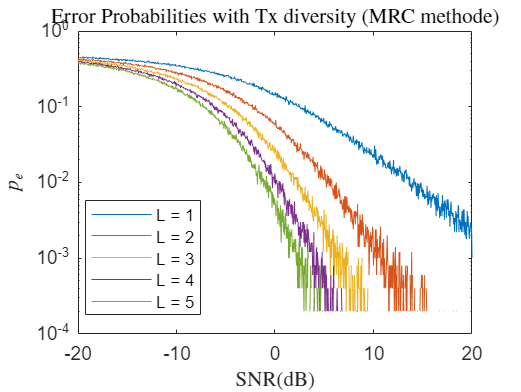

clc;
clear all;
n = 1000;
N = 5000;
SNR = linspace(-20,20,n);
a = 1;
N0 = a^2./(10.^(SNR./10));
W = repmat(N0, [N, 1]);
L = 5;
Pe_sim = zeros(L, n);
for l = 1:5
    Pe_sim(l,:) = Pe_Tx_Diversity(l, N, n, W);
end
semilogy(SNR, Pe_sim(1,:), SNR, Pe_sim(2,:), SNR, Pe_sim(3,:), SNR, Pe_sim(4,:), SNR, Pe_sim(5,:));
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
legend(["L = 1", "L = 2", "L = 3", "L = 4", "L = 5"],'Location','best');
title('Error Probabilities with Tx diversity (MRC methode)',Interpreter='latex');

## Question 6. 

### Part b.

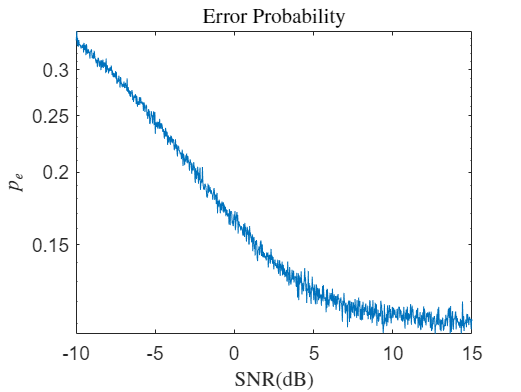

clc;
clear all;
n = 1000;
N = 5000;
ts_num = 2;
SNR = linspace(-10, 15, n);
a = 1;
N0 = a^2./(10.^(SNR./10));
W = repmat(N0, [N, 1]);
w_Re = sqrt(W/2).*randn(N, n, ts_num);
w_Im = sqrt(W/2).*randn(N, n, ts_num);
h_Re = sqrt(1/2)*randn(N, n, ts_num);
h_Im = sqrt(1/2)*randn(N, n, ts_num);
a = [-1,1];
u1 = [];
u2 = [];
parfor i = 1:N
    u1 = [u1 ; randsample(a,n,true)];
    u2 = [u2 ; randsample(a,n,true)];
end
% Generating output signals:
y1_Re = h_Re(:,:,1).*u1 + h_Re(:,:,2).*u2 + w_Re(:,:,1);
y1_Im = h_Im(:,:,1).*u1 + h_Im(:,:,2).*u2 + w_Im(:,:,1);
y2_Re = - h_Re(:,:,1).*u2 + h_Re(:,:,2).*u1 + w_Re(:,:,2);
y2_Im = - h_Im(:,:,1).*u2 + h_Im(:,:,2).*u1 + w_Im(:,:,2);
% Generating detected symbols:
s1 = y1_Re.*h_Re(:,:,1) + y1_Im.*h_Im(:,:,1) + y2_Re.*h_Re(:,:,2) + y2_Im.*h_Im(:,:,2);
s2 = y1_Re.*h_Re(:,:,2) + y1_Im.*h_Im(:,:,2) - y2_Re.*h_Re(:,:,1) + y2_Im.*h_Im(:,:,1);
pe = 1/(2*N)*(sum(s1.*u1 < 0) + sum(s2.*u2 < 0));
semilogy(SNR, pe);
xlabel('SNR(dB)',Interpreter='latex');
ylabel('$p_{e}$',Interpreter='latex');
title('Error Probability',Interpreter='latex');

# **Functions:**

function pe = Pe_Tx_Diversity(L, N, n, W)
    w_Re = sqrt(W/2).*randn(N, n, L);
    w_Im = sqrt(W/2).*randn(N, n, L);
    h_Re = sqrt(1/2)*randn(N, n, L);
    h_Im = sqrt(1/2)*randn(N, n, L);

#### 
$$y=|h|^2 x+h^* w=|h|^2 x+\mathrm{Noise}$$


#### 
$$w=w_{\textrm{Re}} +jw_{\textrm{Im}} \;\;\;\;,\;\;\;\;h=h_{\textrm{Re}} +jh_{\textrm{Im}}$$


#### 
$$h^* w=\left(h_{\mathrm{Re}} -jh_{\mathrm{Im}} \right)\left(w_{\mathrm{Re}} +jw_{\mathrm{Im}} \right)=\left(h_{\mathrm{Re}} w_{\mathrm{Re}} +h_{\mathrm{Im}} w_{\mathrm{Im}} \right)+\left(h_{\mathrm{Re}} w_{\mathrm{Im}} -h_{\mathrm{Im}} w_{\mathrm{Re}} \right)j$$


#### 
$$\textrm{Noise}={\textrm{Noise}}_{\textrm{Re}} +j{\textrm{Noise}}_{\textrm{Im}}$$


    Noise_Re = sum(h_Re.*w_Re + h_Im.*w_Im, 3);
    Noise_Im = sum(h_Re.*w_Im - h_Im.*w_Re, 3);
    Noise = Noise_Re + 1j.*Noise_Im;
    norm2_h = sum(h_Re.^2 + h_Im.^2, 3);
    a = [-1,1];
    x = [];
    parfor i = 1:N
        x = [x ; randsample(a,n,true)];
    end
    y = norm2_h.*x + Noise;
    pe = sum(y.*x < 0)/N;
end